# Stochastic SIR Model

Unlike deterministic models, a **stochastic model** is governed by a stochastic element, which can randomly vary as the simulation is run multiple times. In other words, the term **stochasticity** refers to the property of a system in which the randomness of reality is taken into account, as opposed to analogous deterministic systems.

Another characteristic of a stochastic model is that it obeys to the **Markov rule**, which states that the values of the model at the current moment exclusively depend on its values at the previous moment. If the analysed variables take on discrete values, the model can be called a **Markov chain**:


$$Prob\{I(t_n+1) | I(t_0), I(t_1), ..., I(t_n)\}=Prob\{I(t_{n+1}) | I(t_n)\}$$


What makes stochastic models advantageous in Epidemiology is that they can predict the dynamics of a disease outbreak in terms of probabilities. For instance, if a large number of simulations give overlapping curves, whereas only few simulations produce other results, the pandemics will likely proceed as those repeating curves suggest.

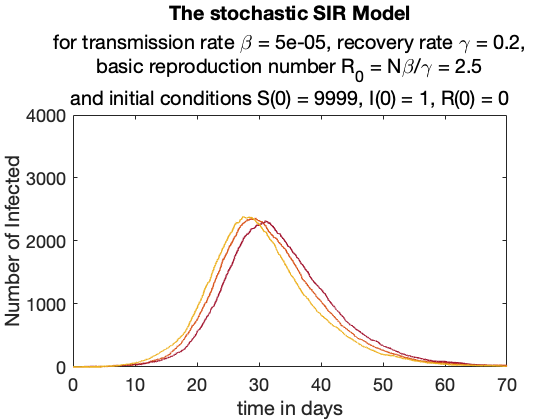

% Continuous Time Markov Chain
% SIR Epidemic Model

clear

set(0, 'DefaultAxesFontSize', 18);
set(gca, 'fontsize', 18);

N = 10000;    % population size

p = 0.1;      % infection probability 
c = 5;        % contact rate

beta = p * c / N;
gamma = 0.2;
R_0 = beta * N / gamma;

I0 = 1;       % initial number of infected
time = 70;    % simulation time
sim = 10;      % No of simulations

for k = 1:sim
    
    clear t S I R
    
    t(1) = 0;
    
    I(1) = I0;
    S(1) = N - I0;
    R(1) = 0;
    
    j = 1;
    
    while I(j) > 0 & t(j) < time
        
        u1 = rand; % uniform random number
        u2 = rand; % uniform random number
        a = beta * I(j) * S(j) + gamma * I(j);
        probI = (beta * S(j)) / (beta * S(j) + gamma);
        t(j+1) = t(j) - log(u1) / a;

        if u2 <= probI
            
            S(j+1) = S(j) - 1;
            I(j+1) = I(j) + 1;
            R(j+1) = R(j);
         
        else
            
            S(j+1) = S(j);
            I(j+1) = I(j) - 1;
            R(j+1) = R(j) + 1;
         
        end
        
    j = j + 1;
    
    end
    
    plot(t, I, '-', 'LineWidth', 1.5)
    hold on

end

title('The stochastic SIR Model')
subtitle({['for transmission rate \beta = ',num2str(beta),', recovery rate \gamma = ',num2str(gamma),','], ...
['basic reproduction number R_0 = N\beta/\gamma = ',num2str(R_0)], ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1)),', R(0) = ',num2str(R(1))]})

axis([0, time, 0, 0.4 * N])

xlabel('time in days');
ylabel('Number of Infected');
hold off